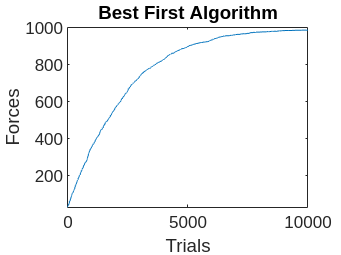

addpath('functions/');

% Creating n Corticalspinal cells
n = 1000;

% Initalize the base CS cells
x_0 = -1 + 2* rand(1, n);

% Parameters for zero-mean normal distribution
std_dev = 0.04;
mean = 0;

% CS extensor and flexor connection weights
flexor_c_fi = [ones(1, n)]; 
flexor_c_ei = [zeros(1, n*0.7), -ones(1, n*0.3)]; 

agonist = randperm(n * 0.99);
antagonist = randsample(agonist,length(agonist) / 3);

% Translating MN pool to force
delta = 1;

final_forces = [];
sei_activations = [];
sfi_activations = [];
f_final_net = 0;
max_trials = 10000;
for trial = 1:max_trials
    v_i = std_dev.*randn(1, n) + mean;
    x_i = x_0 + v_i;

    % Flexor MN Pools translated to force
    s_fi = 0;
    
    for i = 1:length(agonist)
        ind = agonist(i);
        s_fi = s_fi + g_fi(x_i(ind), flexor_c_fi(ind));
    end

    f_f = delta * s_fi;
    f_e = delta * s_ei;

    % Net force
    f_net = f_f ;

    if f_net > f_final_net
        f_final_net = f_net;
        x_0 = x_i;
    end

    sei_activations = [sei_activations, s_ei];
    sfi_activations = [sfi_activations, s_fi];
    final_forces = [final_forces, f_final_net];
end

% plot(trials, forces, trials, final_forces)
plot(final_forces)
title("Best First Algorithm")
ylim([final_forces(1) n])
ylabel('Forces')
xlabel('Trials')

saveas(gcf,'images/BestFirstAlgo.png')

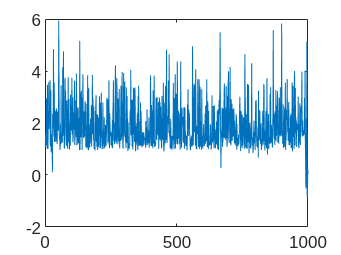

plot(x_0)

function s = g_fi(c_i, x_i)
    % Positive Saturation Limit
    limit = +1;
    s = c_i * x_i;
    if c_i > 0 && s > limit
        s = limit;
    end
end

function s = g_ei(c_i, x_i)
    % Negative Saturation Limit
    limit = -1;
    s = c_i * x_i;
    if c_i < 0 && s < limit
        s = limit;
    end
end

function s = g_efi(c_i, x_i)
    % Positive Saturation Limit
    limit = +1;
    s = c_i * x_i;
    if c_i > 0 && s > limit
        s = limit;
    elseif c_i < 0 && s < -limit
        s = -limit;
    end
end